
% figure R vs Bz %

clear all;
close all;

load('\\Artemis-pc\e\Data\2024-07-13\FreqRatio_reduced.mat');


x(9) = [];
y(9) = [];
err(9) = [];
w(9) = [];

%% 拟合: '无标题拟合 1'。
[xData, yData, weights] = prepareCurveData(x, y, w);

% 设置 fittype 和选项。
ft1 = fittype( 'sqrt(R^2*(x)^2+I171^2-2*I171*R*(x)*a)/sqrt(1^2*(x)^2+I173^2-2*I173*1*(x)*a)',...
    'independent', 'x', 'dependent', 'y' );
opts1 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts1.Display = 'Off';
opts1.Lower = [0 0 0.7260 -0.5];
opts1.Upper = [2 2 Inf 0.5];
opts1.StartPoint = [1 1 0.72608 0];
opts1.Weights = weights;

% 对数据进行模型拟合。
[fitresult1, gof1] = fit( xData, yData, ft1, opts1 );
R1 = fitresult1.R;

interval = confint(fitresult1);
R1_sigma = (interval(2,3)-interval(1,3))/4;


% 计算 Chi square %
chi_square = 0;
for k1 = 1:length(x)
    temp1(k1) = (y(k1)-fitresult1(x(k1)))^2;
    chi_square = chi_square + w(k1)*temp1(k1);
end
chi_square = chi_square/(length(x)-4);



err_mod = err.*sqrt(chi_square);
w_mod = 1./err_mod.^2;

[xData, yData, weights] = prepareCurveData(x, y, w_mod);
opts1.Weights = weights;

% 对数据进行模型拟合。
[fitresult_mod, gof1] = fit( xData, yData, ft1, opts1 );
R_mod = fitresult_mod.R;

interval = confint(fitresult_mod);
R_sigma_mod = (interval(2,3)-interval(1,3))/4;

% 计算 Chi square %
chi_mod = 0;
for k1 = 1:length(x)
    temp1(k1) = (y(k1)-fitresult_mod(x(k1)))^2;
    chi_mod = chi_mod + w_mod(k1)*temp1(k1);
end
chi_mod = chi_mod/(length(x)-4);



% 绘图 %

f1 = figure; hold on;
E1 = errorbar(x,y,err_mod,'o', LineWidth=2, MarkerSize=6);

E1.CapSize = 0;
E1.MarkerEdgeColor = [0.04,0.59,0.83];
E1.MarkerFaceColor = [0.29,0.91,0.91];
E1.Color = [0.45,0.63,0.67];

set(gca,'FontSize',17,'FontName','Times New Roman','FontWeight','bold',...
    'YScale','linear','XScale','linear');

x_low = -105;
x_high = 105;
y_low = 0.726;
y_high = 0.7263;
xlim([x_low,x_high]);
ylim([y_low,y_high]);
xticks([-100 -50 0 50 100]);
yticks([0.726 0.7261 0.7262 0.7263]);
grid off;
box off;


l1 = plot(fitresult_mod);
l1.Color = [0.32 0.56 0.62];
l1.LineWidth = 2;

plot([x_low x_high],[y_high y_high],'Color',[0.15 0.15 0.15]);
plot([x_high x_high],[y_low y_high],'Color',[0.15 0.15 0.15]);

legend('','',['\gamma_{171}/\gamma_{173} = ',num2str(roundn(R_mod,-6),'%.6f'),'(',num2str(round(R_sigma_mod*1e6)),')'],'','', ...
      'Position',[0.357 0.763 0.425 0.0738],'FontSize',14);

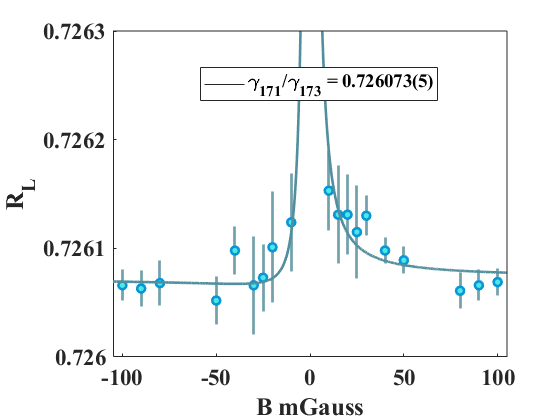


xlabel('B mGauss');
ylabel('R_L');

% ax = axes('Position',get(gca,'Position'),'Color','none',...
%     'XAxisLocation','top','YAxisLocation','right',...
%     'XColor','k','YColor','k');
% set(ax,'XTick',[]);
% set(ax,'YTick',[]);

hold off;

set(f1,'Visible','on');

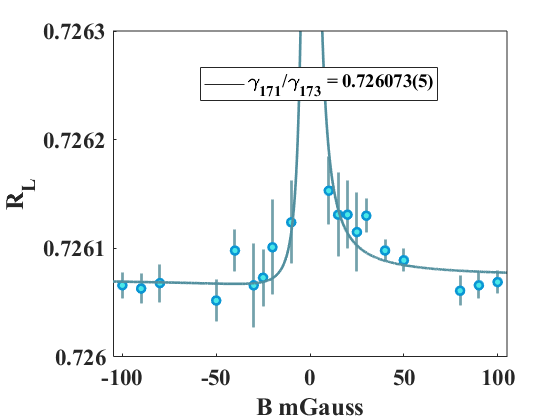


savefig(f1,'E:\Comagnetometer_Pub\RvsBz\RvsBz.fig');
saveas(f1,'E:\Comagnetometer_Pub\RvsBz\RvsBz.png');
saveas(f1,'E:\Comagnetometer_Pub\RvsBz\RvsBz.eps','psc');
saveas(f1,'E:\Comagnetometer_Pub\RvsBz\RvsBz.svg');


save('E:\Comagnetometer_Pub\RvsBz\RvsBz.mat');